# Fourier Analysis of Signals Using DFT (250 Points)

**Dear Student, **

**Welcome to Lab 2! At the end of this lab, you will be able to **

- **find out an estimate of frequency content of a discrete-time sequence,  **

- **comment on resolution and leakage of a window and its impact on the frequency analysis, and **

- **compare different types of windows.**

- **use short-term Fourier transform and obtain power spectral density of a signal. **

Let $x[n] =  A_0\cos(w_0n) +  A_1\cos(w_1n), n \in \mathbb{Z}$ be the discrete-time signal obtained by sampling $x(t)$with sampling frequency $T_s$. 

Write down possible expressions for $x(t)$ here:  $x\left(t\right)=A_{0\;} \cos \left(\frac{w_o }{T_s }\ldotp t\right)+A_{1\;} \cos \left(\frac{w_1 }{T_s }\ldotp t\right)$ 

Usually, we cannot obtain the sequence $x[n]$for all the time duration, i.e., for $-\infty $to $+\infty
$. Further, even if you are able to collect a large number of samples, we will not be able to compute its DFT for frequency analysis.  Let us assume that we have $x[n]$values available for $0\leq n\leq L-1$only using which we are required to do frequency analysis. One way to go forward is, we assume that $x[n]=0$ for $n\notin \{0,L-1\}$.  That is, we have the windowed sequence, $v[n]$, defined as follows:$v[n] = x[n]w[n]$, where $w[n] = 1$for $0\leq n\leq L-1$ and $w[n] =0$, otherwise. This window is called as the rectangular window. 

#### Coding Question (10 points)

Write a code to get $x[n], w[n] $and $v[n]$

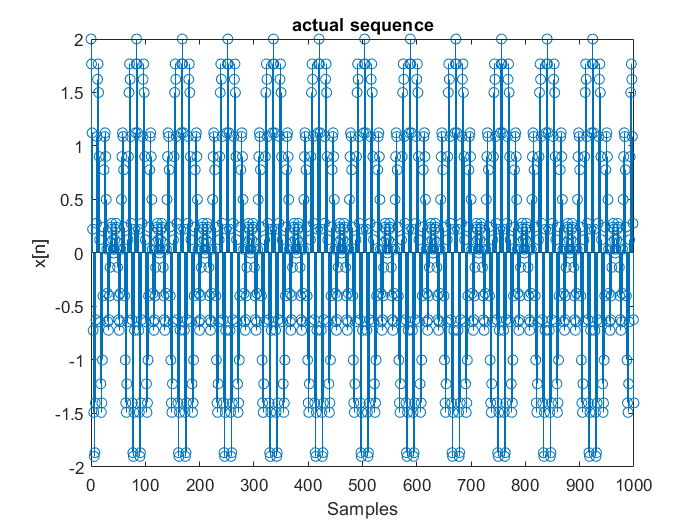

w0 = 2*pi/3;
w1 = 2*pi/6;
A1 = 1;
A2 = 1;
L =  128; % Window length

n = 0 : 1 : 1000;

x = A1*cos(w0*n) + A2*cos(w1*n); % EXERCISE: Construct x[n] defined above  

rectWindow = (n>=0 & n < L); % EXERCISE Define a rectangular window of length L, w[n]

v =  x.*rectWindow; % EXERCISE: Compute the windowed sequence, v[n]

v = v(1:L);

stem(n,x);
xlabel('Samples');
ylabel('x[n]');
title('actual sequence');

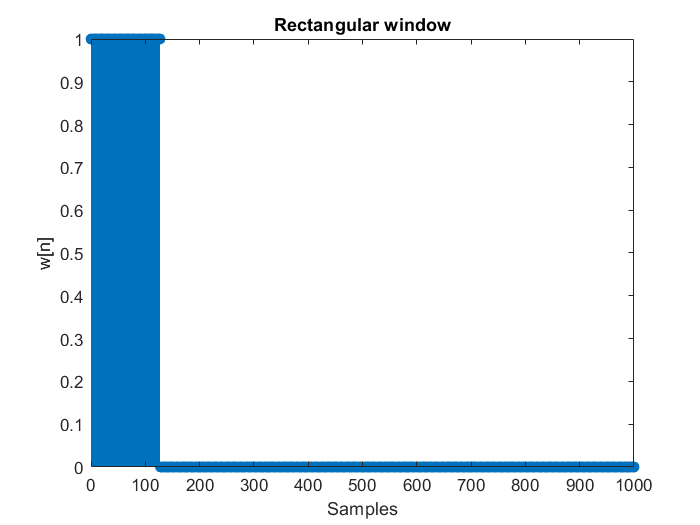

stem(n,rectWindow);
xlabel('Samples');
ylabel('w[n]');
title('Rectangular window');

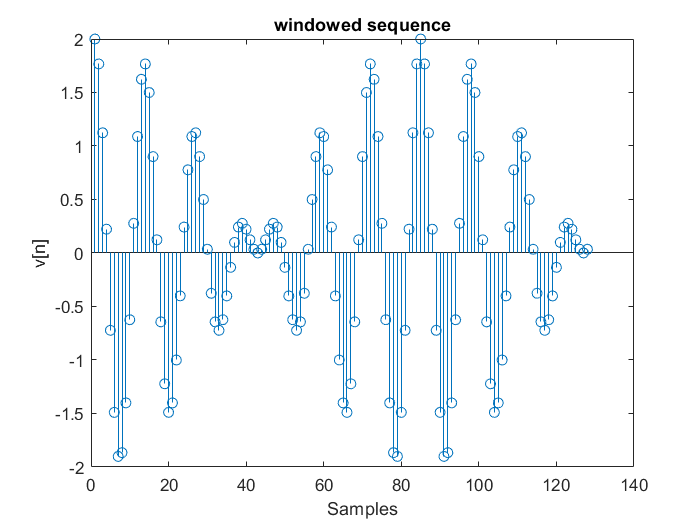

stem(v);
xlabel('Samples');
ylabel('v[n]');
title('windowed sequence');

Now, we will compute its DFT using the Matlab in-built function ([fft](https://in.mathworks.com/help/matlab/ref/fft.html)). 

#### Coding Question (10 points)

Compute $N$-point DFT, $V[k]$ of $v[n]$ and plot $V[k]$ from $k\in [0, N-1]$

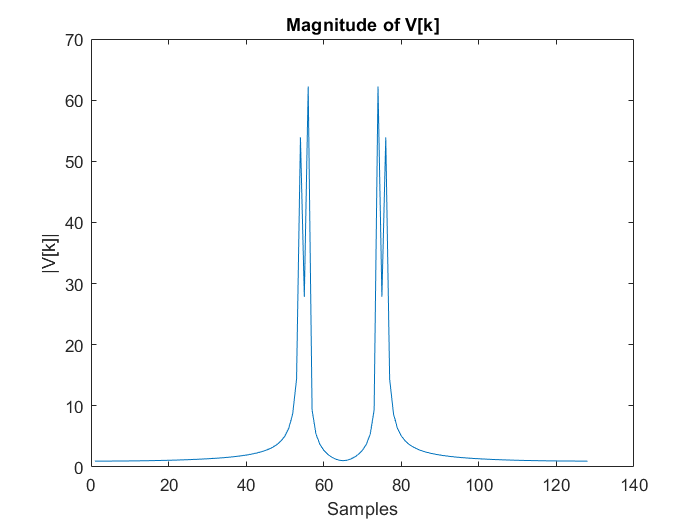

N = L; % EXERCISE: Define a suitable N
 
V = fftshift(fft(v,N)); % EXERCISE: Compute N-point DFT

plot(abs(V)); %  EXERCISE: Plot Magnitude of V
xlabel('Samples');
ylabel('|V[k]|');
title('Magnitude of V[k]');

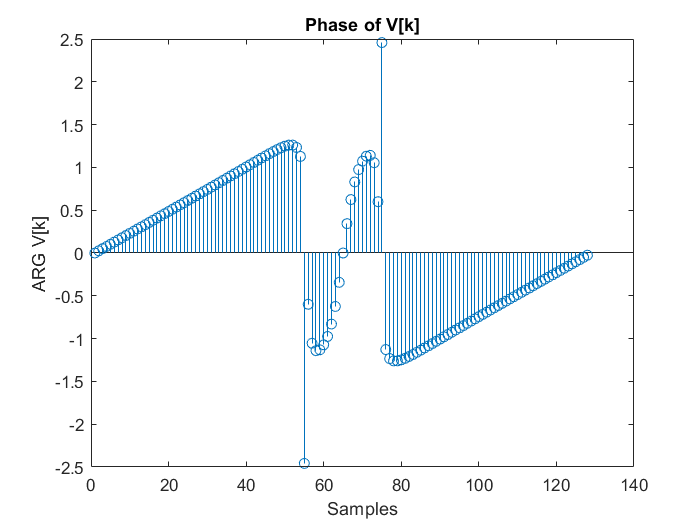


stem(angle(V)); %  EXERCISE: Plot Phase of V
xlabel('Samples')
ylabel('ARG {V[k]}')
title('Phase of V[k]')

It is bit difficult to read the above plots as we do not readily see which samples correspond to which discrete-time frequency. Hence, let us try to view the DTFT of v[n] (approximate). Let us first compute the DTFT of $w[n]$.

#### Coding Question (10 points)

Compute the DTFT of w[n] and display its magnitude and phase response in $[-\pi,\pi]$. 

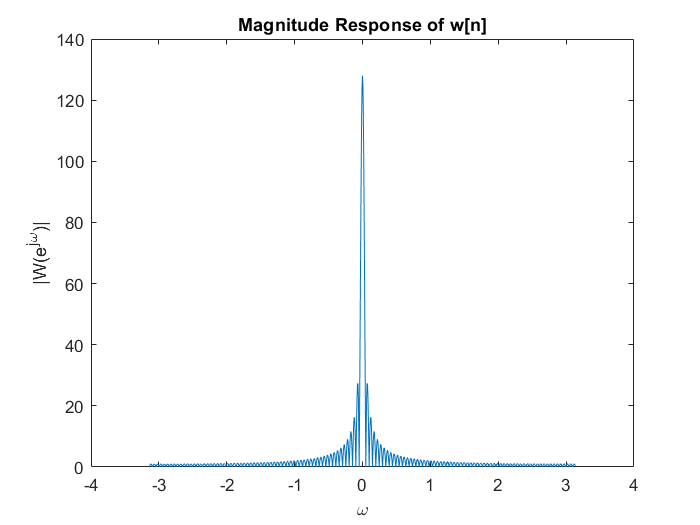

N = 1024; % EXERCISE: Define a suitable N

k = -N/2 : 1 : (N/2)-1;
omega = k*2*pi/N; % EXERCISE: Compute sample points of discrete-time frequency

W = fftshift(fft(rectWindow,N)); % EXERCISE: Compute N-point DFT
plot(omega,abs(W)); %  EXERCISE: Plot Magnitude  of V
xlabel('\omega')
ylabel('|W(e^{j\omega})|')
title('Magnitude Response of w[n]')

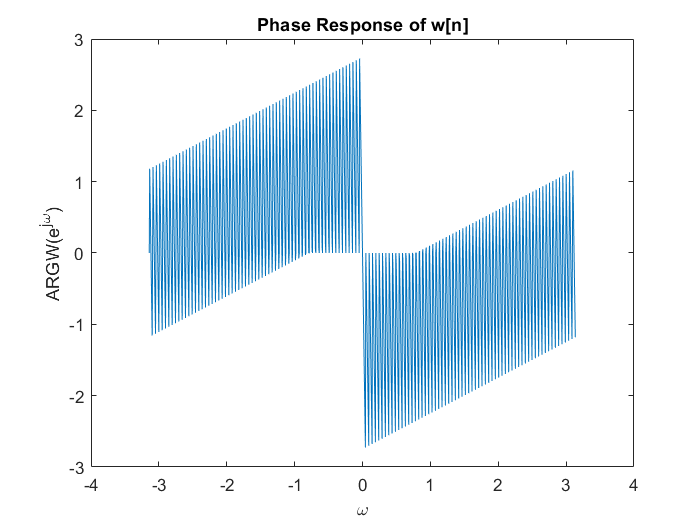

plot(omega,phase(W)); %  EXERCISE: Plot Magnitude  of V
xlabel('\omega');
ylabel('ARG{W(e^{j\omega})}');
title('Phase Response of w[n]');

#### Coding Question 10 points)

Compute the DTFT of v[n] and display its magnitude and phase response in $[-\pi,\pi]$. 

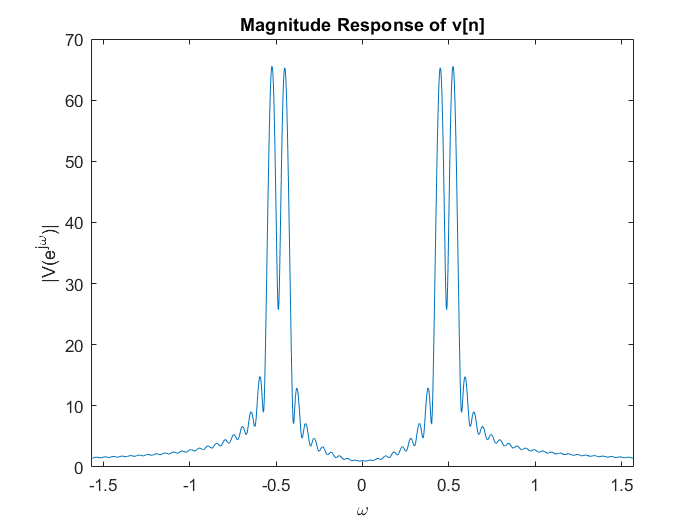

% EXERCISE: Define a suitable N
N = 10000; %choosing a very High value of N as increasing N tends DFT to DTFT
 
% EXERCISE: Compute sample points of discrete-time frequency
k = -N/2 : 1 : (N/2)-1;
omega = k*2*pi/N;

% EXERCISE: Compute N-point DFT 
V = fftshift(fft(v,N)); 
 
%  EXERCISE: Plot Magnitude  of V
plot(omega, abs(V));
xlabel('\omega');
ylabel('|V(e^{j\omega})|');
xlim([-pi/2 pi/2]);
title('Magnitude Response of v[n]');

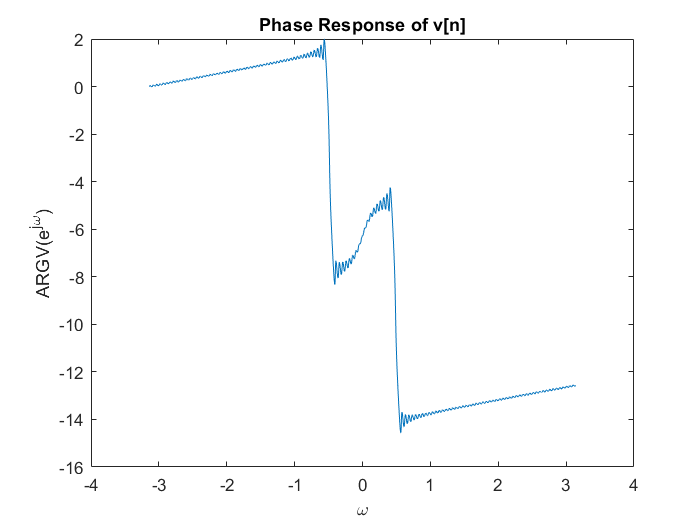

plot(omega, phase(V)); %  EXERCISE: Plot Magnitude  of V
xlabel('\omega');
ylabel('ARG{V(e^{j\omega})}');
title('Phase Response of v[n]');

#### Coding Question  (10 points)

Now, suppose the $x(t)$ was sampled at sampling period of $T_s$, then plot $X(j\Omega)$, your estimate of the continuous-time Fourier transform of $x(t)$. 

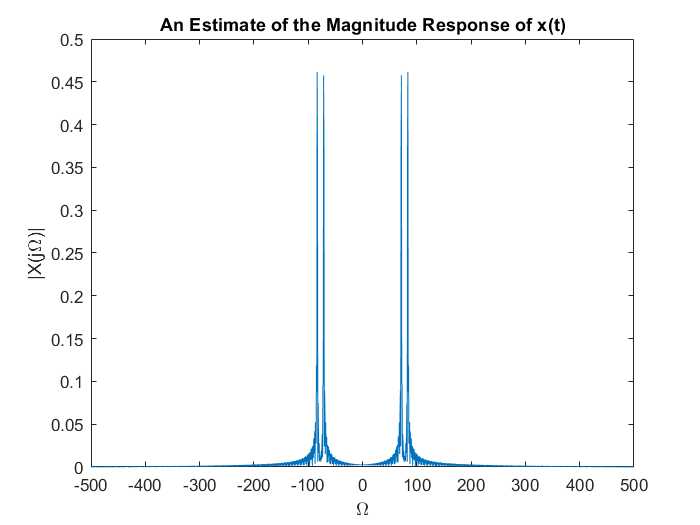

Ts = [1/1000] ; % EXERCISE: Choose a sensible sampling frequency

Omega = [omega/Ts]; % EXERCISE: Construct continuous-time frequency from discrete-time frquency

t = 0:Ts:1000*Ts;

for i = 1:length(Omega)
    
    X_jOmega(i) = trapz(t,x.*(exp(-1i*2*pi*Omega(i)*t)));
    
end

plot(Omega, abs(X_jOmega)); %  EXERCISE: Plot Magnitude  of V
xlabel('\Omega')
ylabel("|X(j\Omega)|")
xlim([-1/(2*Ts) 1/(2*Ts)]);
title('An Estimate of the Magnitude Response of x(t)')

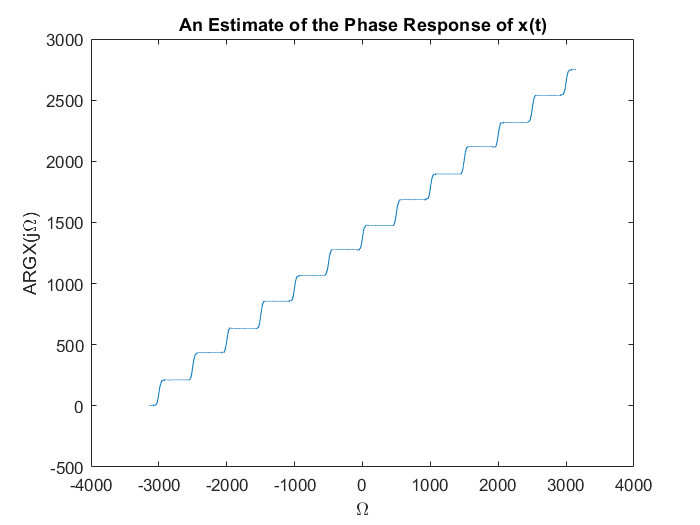

plot(Omega, phase(X_jOmega)); %  EXERCISE: Plot Magnitude  of V
xlabel('\Omega')
ylabel('ARG{X(j\Omega)}')
title('An Estimate of the Phase Response of x(t)')

#### Inference Question (40 points)

Now, repeat the above four questions for 

- 
$$w_0 = 2\pi/14, w_1 = 2\pi/15$$


- 
$$w_0 = 2\pi/14, w_1 = 2\pi/12$$


- 
$$w_0 = 2\pi/14, w_1 = 4\pi/25$$


- What do you observe on the number of peaks?  

- How does your observation change if you change $L$? 

- How does your observation change if you change $N$? 

- Do the amplitudes of $|V[k]|$reflect that of $|V(e^{j\omega})|$? Why? 

- Do the amplitudes of $|V(e^{j\omega})|$ reflect that of $|X(e^{j\omega})|$?  Why? 

    * WRITE YOUR ANSWER HERE.*

*1) For *$w_0 = 2\pi/14, w_1 = 2\pi/15$ we can 

- we can observe only 2 peaks in our V[k] plot for L = 128. this is because the frequencies are very close and are not resolved as different frequencies

- when we increase the value of L we are able to see a little difference between the peak for the different frequencies. hence when we increase L our resolution increases.

- on decreasing the value of N the peak values decrease and they become less sharp, whereas when we increase the value of N the peak values come to constant and we are also able to observe the side lobes (the small peaks) hence the plot tends towards DTFT as we increase N.

- Yes, the Amplitdes of $|V[k]|$reflect that of $|V(e^{j\omega})|$ because we have chosen L and N as 128, if we select N which is lesser than the value of L then ve will get blunt peaks which have lesser amplitudes in $|V[k]|$ as compared to $|V(e^{j\omega})|$.

- No, the amplitudes of $|V(e^{j\omega})|$ do not match that of $|X(e^{j\omega})|$. Instead they are scaled . this can be interpreted as follows - when we windowed our sequence x[n] we considered only a small part of our signal and not the complete signal hence the energy of that windowed signal will be just be a fraction of the total energy hence the peaks are different. additionally in a real scenario when we consider the continuous fourier transform the peaks are Delta functions where the peak goes to infinity, but here we are not taking the Continuous time fourier transform instead we are sampling the sequence with a sampling period Ts, hence the peaks shown in the plot of $|X(e^{j\omega})|$ are also proportional to Ts.

2) For $w_0 = 2\pi/14, w_1 = 2\pi/12$ we can observe 4 distinct peaks for L = 128, but when we decrase L, instead of obtaining 4 peaks we get only two peaks as the closer peaks merge due to lesser resolution. all the other observations are same 

3) For $w_0 = 2\pi/14, w_1 = 4\pi/25$ we can observe $ distinct peaks for L = 128, but the closer peaks merge when we decrease L below 64. all the other observations are same 

In the above, we observed $x[n]$ through a rectangular window. Let's now observe $x[n]$ through other types of windows and explore what we will see. 

Now, use this link for help ([https://in.mathworks.com/help/dsp/ref/windowfunction.html](https://in.mathworks.com/help/dsp/ref/windowfunction.html)) and compute the DTFT of $v[n]$ over $[-\pi, \pi]$when

- $w[n]$is a Hamming window

- $w[n]$is a Hanning window

- $w[n]$is a Bartlet window

- $w[n]$is a Kaiser window

Note that you have already used the Boxcar window earlier above. 

#### Coding Question  (40 points)

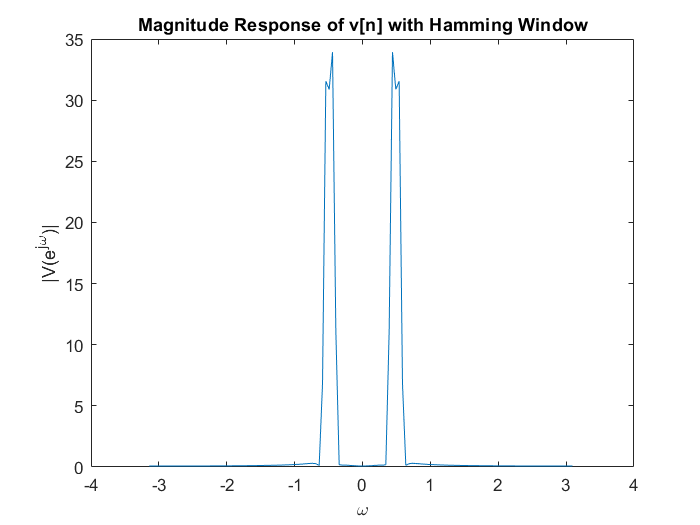

% COMPUTE and PLOT DTFT OF v[n] WHEN w[n] IS A HAMMING WINDOW
hamming_window = hamming(L);
window1 = zeros(1,1001);
for i = 1 : L
    window1(i) = hamming_window(i);
end

v = x.*window1;
N = L;
k = -N/2 : 1 : (N/2)-1;
omega = k*2*pi/N;
V = fftshift(fft(v,N));

plot(omega, abs(V));
xlabel('\omega');
ylabel('|V(e^{j\omega})|');
title('Magnitude Response of v[n] with Hamming Window');

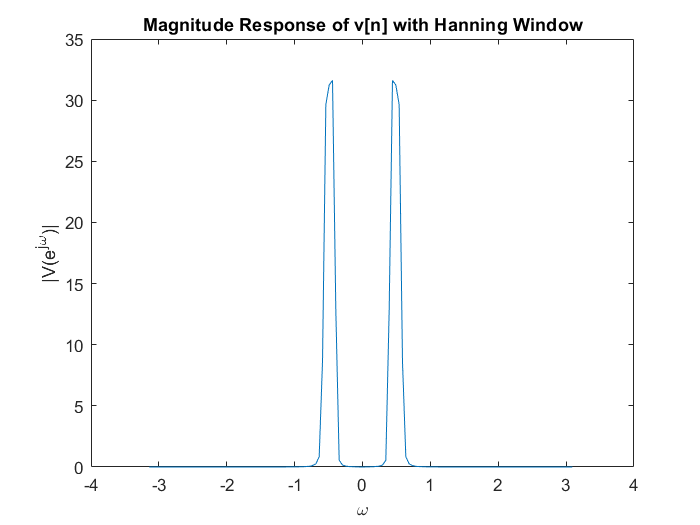

% COMPUTE and PLOT DTFT OF v[n] WHEN w[n] IS A Hanning WINDOW
hanning_window = hann(L);
window2 = zeros(1,1001);
for i = 1 : L
    window2(i) = hanning_window(i); 
end

v = x.*window2;
N = L;
k = -N/2 : 1 : (N/2)-1;
omega = k*2*pi/N;
V = fftshift(fft(v,N)); 
 
plot(omega, abs(V));
xlabel('\omega');
ylabel('|V(e^{j\omega})|');
title('Magnitude Response of v[n] with Hanning Window');

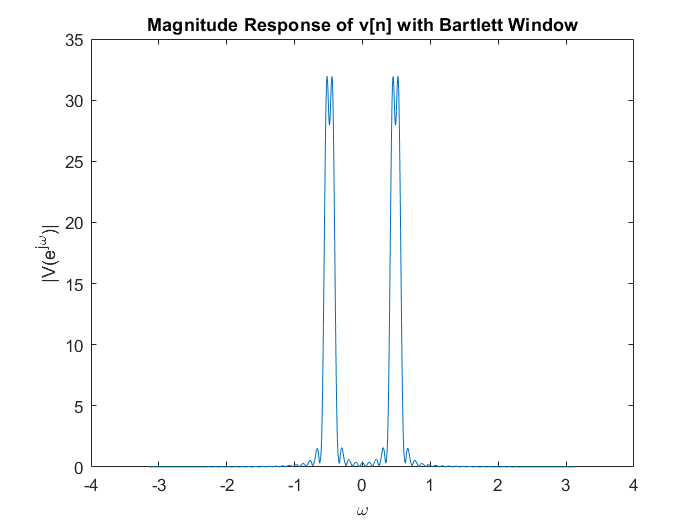

%  COMPUTE and PLOT DTFT OF v[n] WHEN w[n] IS A Bartlet WINDOW

bartlett_window = bartlett(L);
window3 = zeros(1,1001);
for i = 1 : L
    window3(i) = bartlett_window(i); 
end
v = x.*window3;
N = 1024;
k = -N/2 : 1 : (N/2)-1;
omega = k*2*pi/N;
V = fftshift(fft(v,N)); 

plot(omega,abs(V));
xlabel('\omega');
ylabel('|V(e^{j\omega})|');
title('Magnitude Response of v[n] with Bartlett Window');

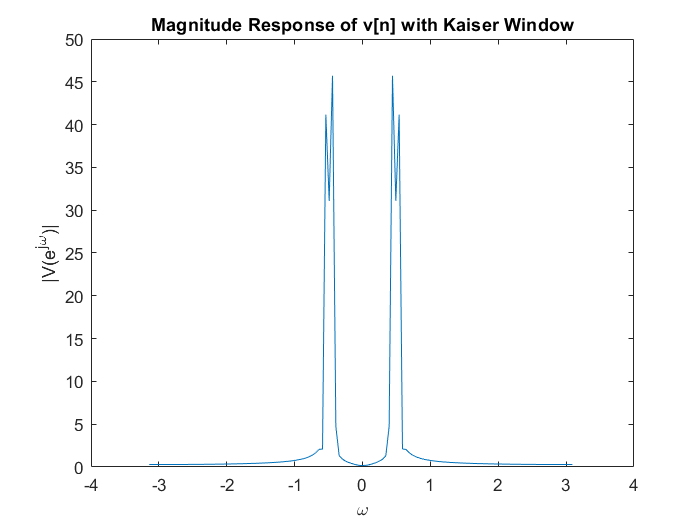

%  COMPUTE and PLOT DTFT OF v[n] WHEN w[n] IS A Kaiser WINDOW

kaiser_window = kaiser(L,2.5);
window4 = zeros(1,1001);
for i = 1 : L
    window4(i) = kaiser_window(i); 
end

v = x.*window4;

N = L;
k = -N/2 : 1 : (N/2)-1;
omega = k*2*pi/N;
V = fftshift(fft(v,N)); 
 
plot(omega, abs(V));
xlabel('\omega');
ylabel('|V(e^{j\omega})|');
title('Magnitude Response of v[n] with Kaiser Window');

#### Inference Question  (20 points)

- What do you observe on the number of peaks and their amplitudes?

- Give a short comparison of different windows on  the above terms (on the number of peaks and their amplitudes) that you can observe. 

    * WRITE YOUR ANSWER HERE.*

*We have considered  *$w_0 = 2\pi/14, w_1 = 2\pi/12$ to illustrate the differences in ech window.

- In the case of Hamming window, we can observe two peaks with two heads each instead of 4 different peaks. Also their amplitude is considerably lesser than the actual DTFT of the sequence.

- In the case of Hanning window, we can observe only two peaks instead of 4. Also their amplitude is very less as compared to actual DTFT of the sequence, this is because the peaks are blunt.

- In the case of Bartlett window, we can observe two peaks with two heads each instead of 4 different peaks these are better than the ones in Hamming window. Also their amplitude is considerably lesser than the DTFT of the sequence.

- In the case of Kaiser window, we can observe 4 peaks, better than anyother widow in comparision. We can also observe that the peaks have different amplitudes this is due to leakage. The amplitude in this case is higher and comparable to the actual DTFT.

## Short-Time Fourier Transform (50 Points)

In the above material, we assume that the frequencies and amplitudes of the sinusoids do not change with time. However, in practice, usually amplitudes and frequencies of a signal change with time. For analyzing the frequency content of that we consider only a small window and analyse its frequency content, and slide the window to look at the frequency content of the next window and so on. This is called the Short-Time Fourier Transform. 

Now read the first page of Section 10.3 of "Discrete-Time Signal Processing", 2nd Edition by Alan V. Oppenheim, Ronald Schafer and John R. Buck. 

- How is the short-time Fourier transform defined as, for a sequence $x[n]$.

        ANSWER:  $ ENTER~YOUR~ANSWER~HERE$

Short Time fourier Transform is just an extension of the above concept. In a real world signal (speech signal) we will not have only one or two  frequencies in the whole signal, these frequencies will keep varying as time passes, hence we come up with Short time fourier transforms,  here we take only a small part of our signal and find the DTFT of that portion so as to get a better Idea, about the frequency distribution at that time.

To do this we, we window the original signal at at a specefic instant of time, and then compute its DTFT. After this we keep on shifting this window to get different portions of our signal and find the corresponding DTFTs.  

the equation is of STFT is:

                        
$$X\left\lbrack n,l\right\rbrack =\sum_{m=-\infty }^{\infty } {x\left\lbrack n+m\right\rbrack w\left\lbrack m\right\rbrack e}^{-\textrm{jlm}}$$


as we can see above instead of shifting the window we are shifting the signal by n.

here x[n+m] is the shifted signal and w[m] is the window. 

- Now, construct the following frequency modulated chirp signal: $x[n] = \cos(\omega_0 n^2), $ where $\omega_0 = 2\pi\times 7.5\times10^{-6}. $

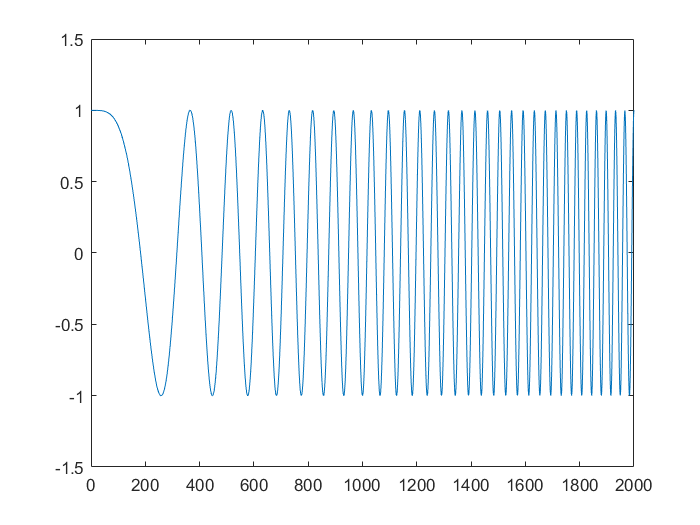

w0 = 2*pi*7.5e-06;
n = 0 : 1 : 10000;
x = cos(w0*(n.*n));

plot(n,x);
xlim([0 2000]);
ylim([-1.5 1.5]);

- Now compute the short-term Fourier transform of $x[n], $ with rectangular window, $w[n]$  of some L  length. 

L  = 256; % LENGTH OF THE RECTANGULAR WINDOW

w = n < L; % RECTANGULAR WINDOW

omega = 0:pi/(L-1):pi;

X_stft = zeros(length(n) - L,length(omega)); % COMPUTE STFT of x[n] using rectnagluar window w[n].

for i = 1 : 20 : length(n) - L 
    
    for j = 1 : L
        
        for m = 1 : L
            X_stft(i,j) = X_stft(i,j) + x(i + m - 1)*w(m)*exp(-1i*omega(j)*m);
        end
                
    end
        
end

clims = [0 60];
fig = figure;
imagesc(n,omega,abs(X_stft'),clims);
colorbar;
axis xy;
xlabel('samples (n)');
ylabel('FREQUENCY (Hz.)');

- Now use [spectrogram](https://in.mathworks.com/help/signal/ref/spectrogram.html) to compute the short-time Fourier transform of the above $x[n]$ and compare it with what you had got. 

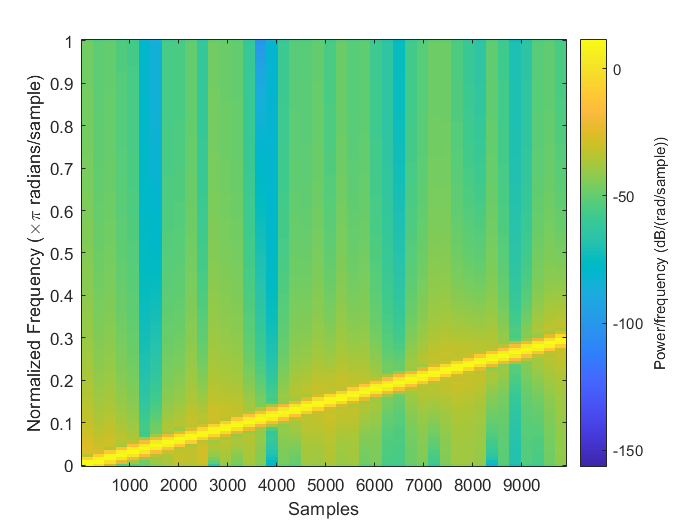

%WRITE YOUR CODE HERE
spectrogram(x,L,20,'yaxis');


plot(n);
title('buffer plot');


# Practical Experiment (50 Points)

- Now count 1 to 5 in any language of your interest (try your mother tongue) and record it.

% COUNT 1-5 AND RECORD IT.
x =  audiorecorder(20000 , 8 , 1);
disp("Recording Started");

Recording Started


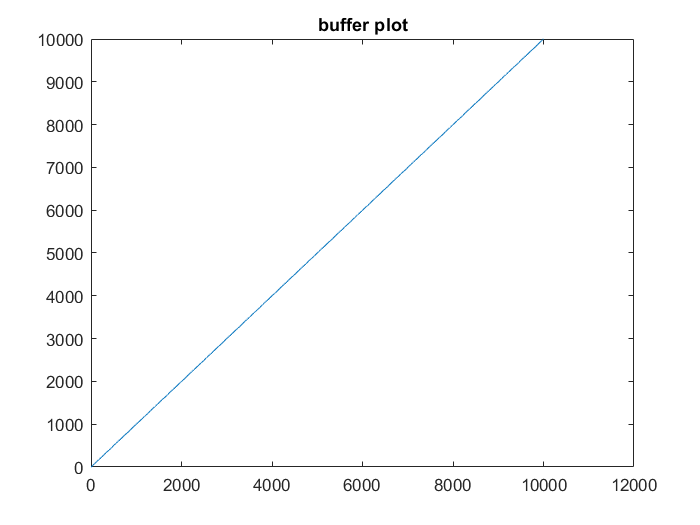

recordblocking(x,10);

disp("Recording finished");

Recording finished


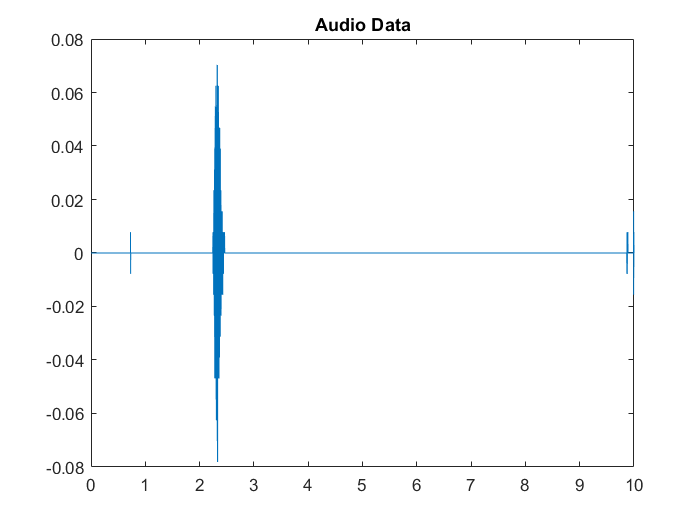

y = getaudiodata(x);

t = 0 : 1/20000 : 10 - 1/20000;
Ts = 1/20000;

plot(t,y);
title('Audio Data');

- Now compute the spectrogram of the signal you have recorded

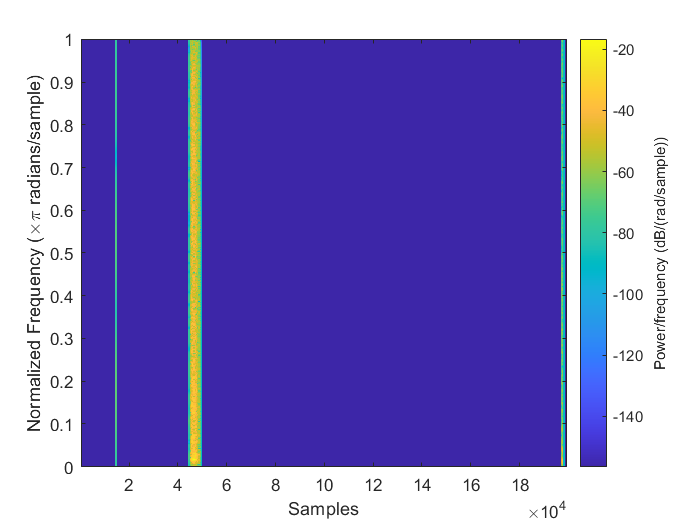

% COMPUTE THE SPECTROGRAM
L = 1024;
omega = 0:pi/(L-1):pi;

spectrogram(y,L,'yaxis');

- Play with different parameters of the spectrogram and write your 3 observations: 

        ANSWER: 

- if we put a parameter *'yaxis' * in the spectogram function, we get the correct representation which is no. of samples in x axis and frequency in y axis.

- When we increase the length of the window given to the spectogram the distinction of frequencies is easier hence we can conclude that the spectral resolution increases if we increase the length of the window.

- When we increase the length of window not only the spectral resolution increases, but the temporal resolution also decreases. hence the distinction in change of frequencies is difficult.

- Lastly we can observe that when we increase the overlap length the spectogram takes a little more time to run as when we increase the overlaps we have to compute more DTFTs as compared to less overlap case. Also increasing the overlap gives us a continuous variation in frequency whereas we get jumps if we have less overlap  

- Now compute the [periodogram](https://in.mathworks.com/help/signal/ref/periodogram.html) of the recorded signal:

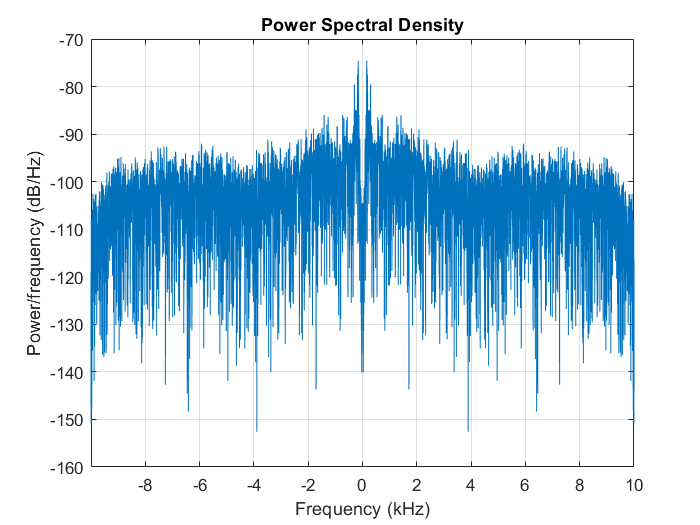

%WRITE YOUR CODE HERE
periodogram(y,[],length(y),20000,'centered')

- What information does the periodogram give? 

        ANSWER: The Periodogram class represents a power spectrum, with values of frequency on the x-axis (in any frequency units) and values of power on the y-axis ,Basically it gives us the information how much power does each frequency component hold in a given data for a given raange of frequencies.

- Until what frequency does human voice contain significant power density? 

        ANSWER: According to my Spectogram human voice contain significant power density until the frequency 500Hz.

## Thank You!